### Question 4

clear all;
close all;
clc;

%declaring constants.

mu = [2 1]'; %mean vector.
K1 = [1 0; 0 1];%Covariance Matrix.
K2 = [1 0.8; 0.8 4];
detK1 = det(K1);
detK2 = det(K2);
K1inv = K1^(-1);
K2inv = K2^(-1);

%generating sample 2D points.

x1 = linspace(-5,5,100);
x2 = linspace(-5, 5, 100);
X = zeros(2, length(x1)*length(x2));
col_ind = 0;
for i = x1
    for j = x2
        col_ind = col_ind + 1;
        X(:, col_ind) = [i ;j];
        % disp(col_ind)
    end
end

%defining multivariate gaussian distribution.

y1 = zeros(length(X), 1);
y2 = zeros(length(X), 1);
norm_const = (1/(sqrt(((2*pi)^2)*detK1)));
for i = 1:length(X)
    y1(i) = norm_const * exp((-0.5)*(X(:,i)-mu)'*K1inv*(X(:,i)-mu));
    y2(i) = norm_const * exp((-0.5)*(X(:,i)-mu)'*K2inv*(X(:,i)-mu));
end

### Plotting

####     Surface Plots

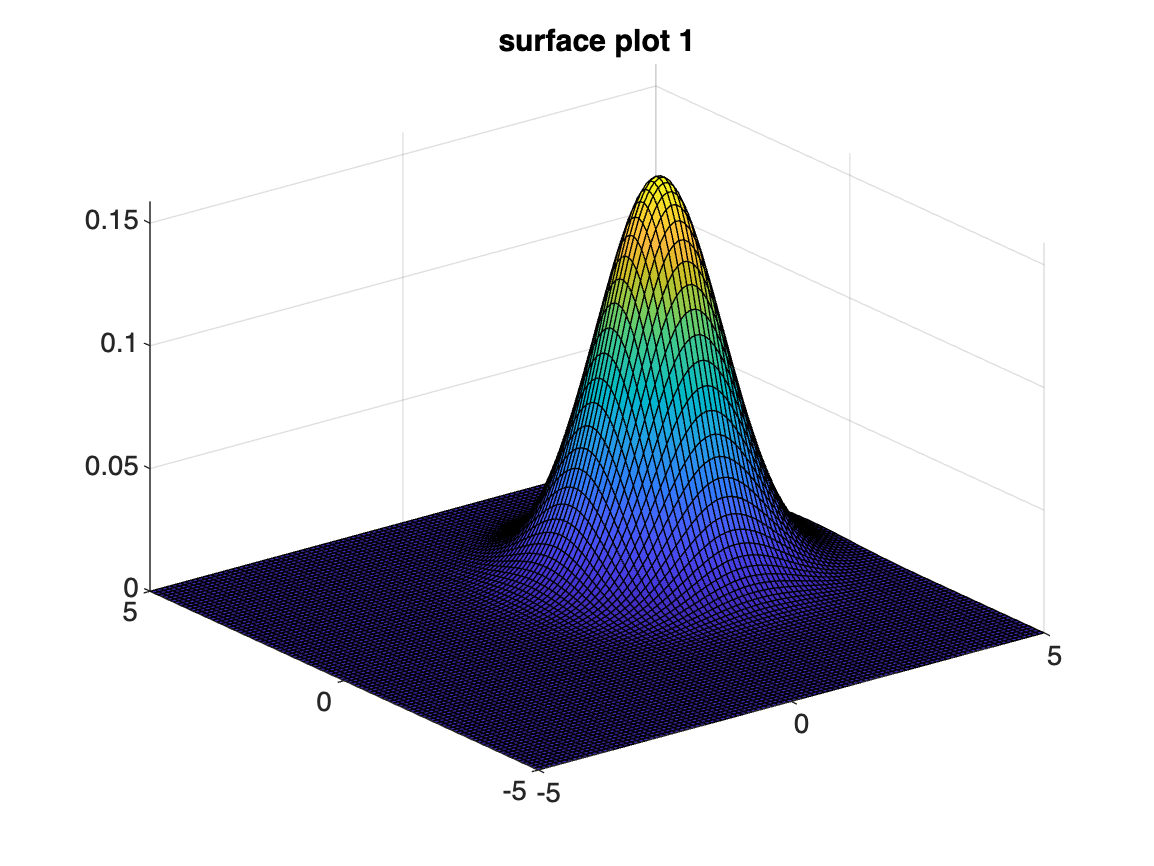

%reshaping linear vectors as matrices so as to plot.
x1axis = reshape(X(1,:),[length(x1) length(x1)]);
x2axis = reshape(X(2,:), [length(x1) length(x1)]);
pdf1axis = reshape(y1,[length(x1) length(x1)]);
pdf2axis = reshape(y2, [length(x1) length(x1)]);
figure(1);
surf(x1axis, x2axis, pdf1axis);
title("surface plot 1");
hold off;

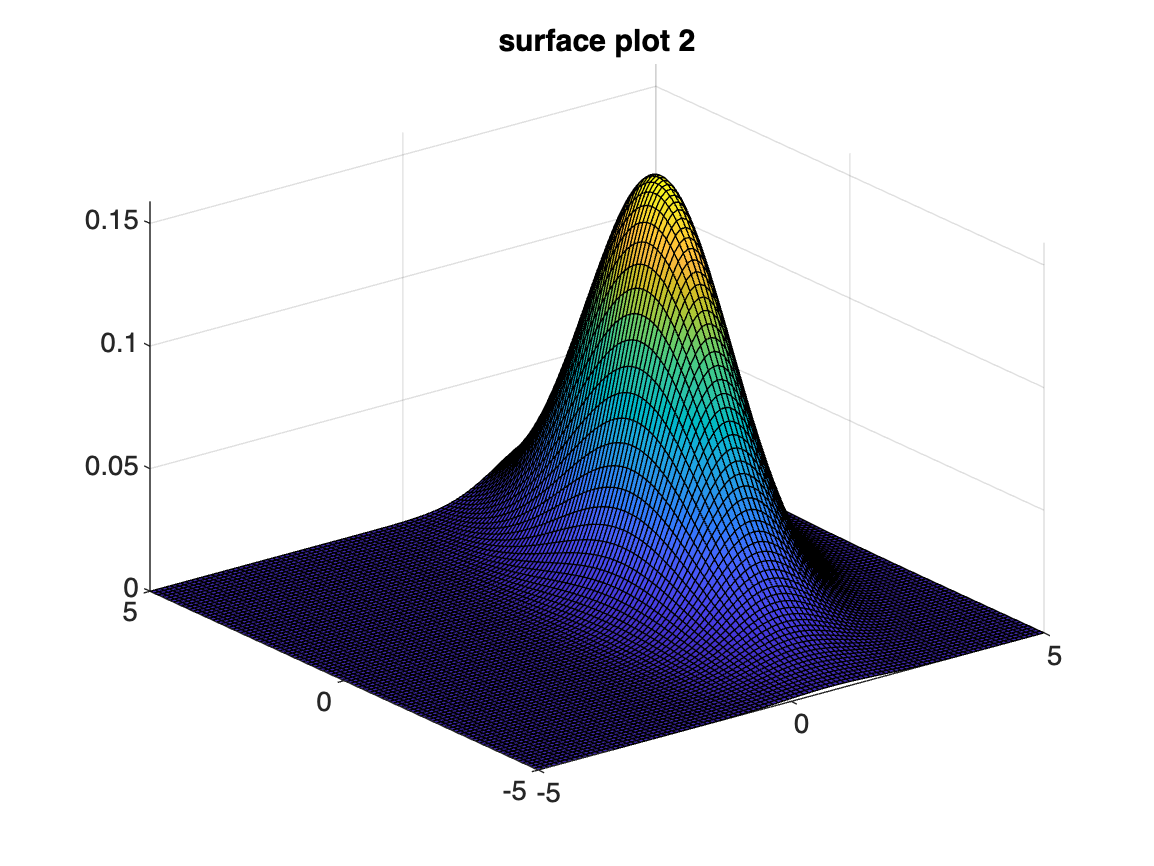

figure(2);
surf(x1axis, x2axis, pdf2axis);
title("surface plot 2");

####     Contour Plots

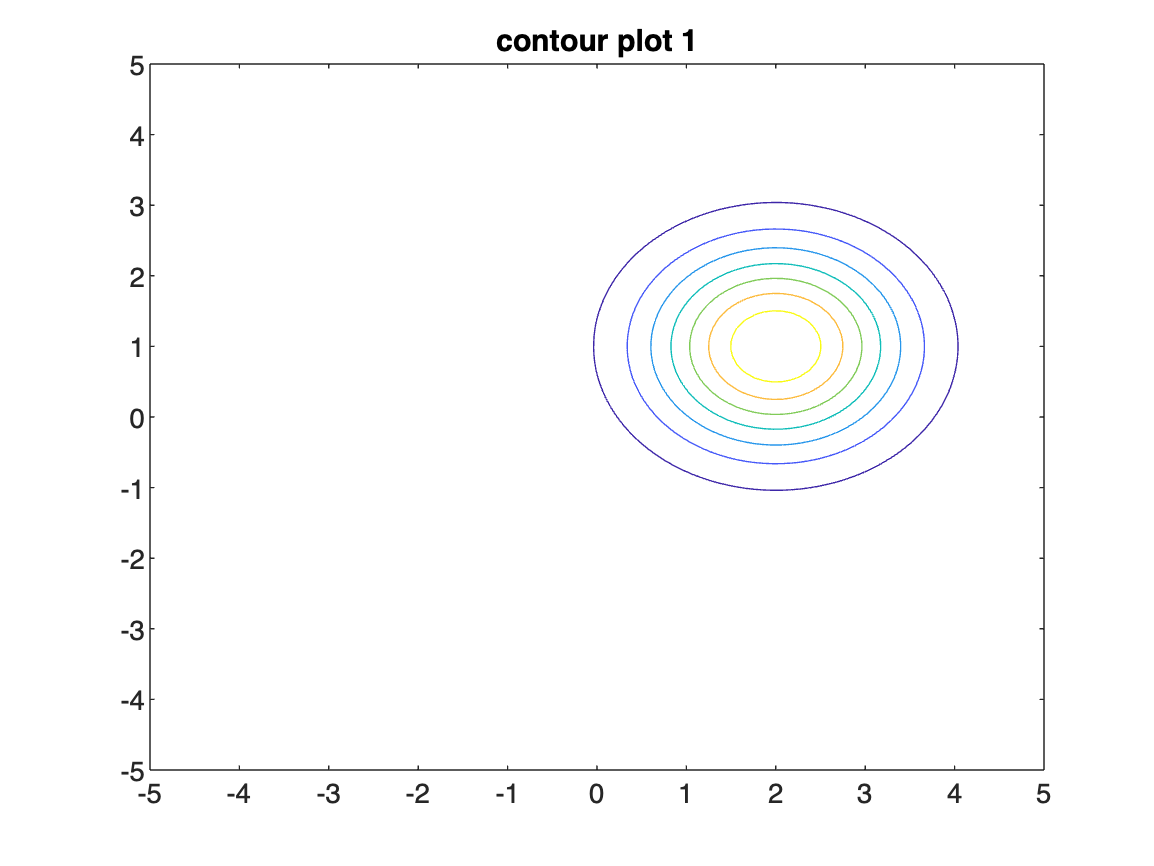

figure(3);
contour(x1axis, x2axis, pdf1axis)
title("contour plot 1");

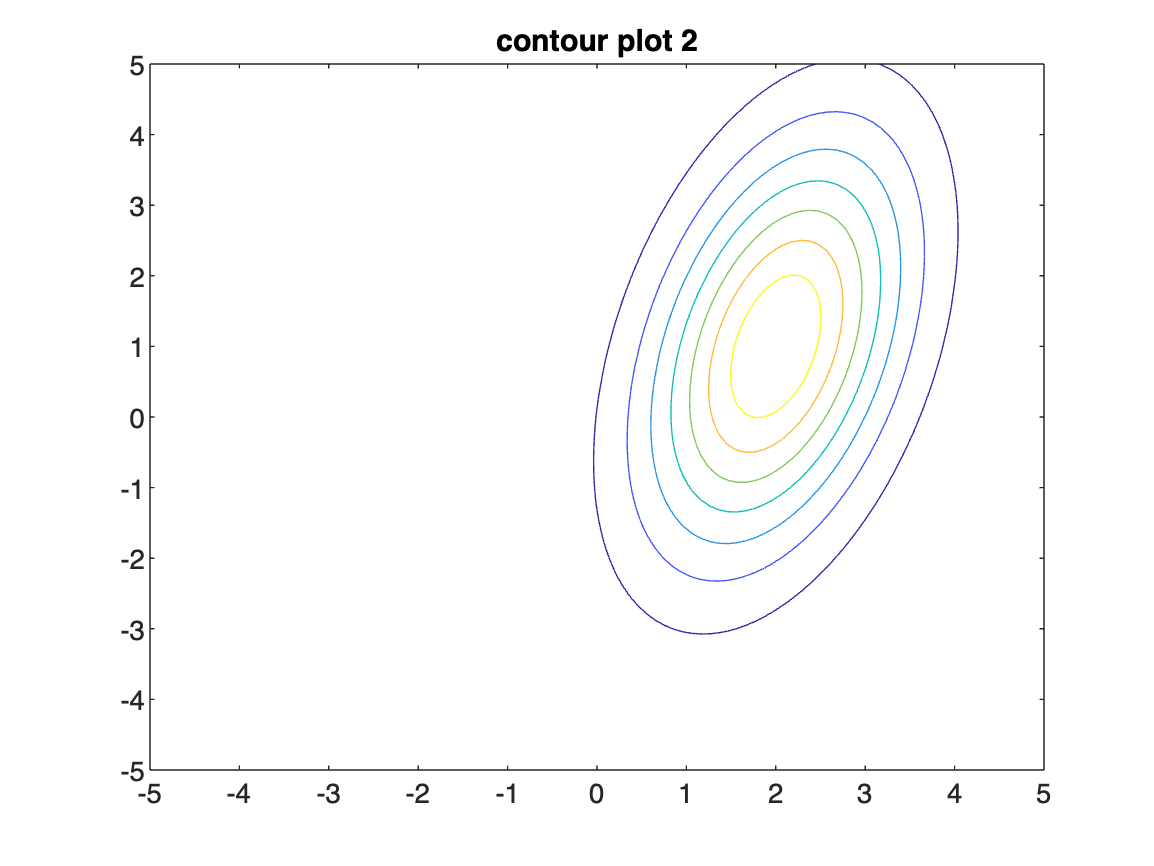

figure(4);
contour(x1axis, x2axis, pdf2axis)
title("contour plot 2");